# OGLO notebook 3

hnxj@github

## 1: X|A vs X|B (trial PEV)

aaab = 1;
axab = 2;
aaxb = 3;
aaax = 4;
bbba = 5;
bxba = 6;
bbxa = 7;
bbbx = 8;
rrrr = 9;
rxrr = 10;
rrxr = 11;
rrrx = 12;

expvard = cell(1, 10);

for k = 1:10

    ntotal = 0;
    expvard{k} = zeros(areaCounts(k), 1500);
    disp(k);

    for l = 1:size(z{k}{1}, 2)

        x1 = z{k}{aaax}{l}(:, :, 3561:5060);
        x2 = z{k}{aaax}{l}(:, :, randperm(1500, 1500)+3560);
        % x3 = z{k}{rrrx}{l}(:, :, randperm(1200, 1200)+3800);
        
        N = min([size(x1, 1), size(x2, 1)]);
        n1 = size(x1, 2);
    
        idx1 = randperm(size(x1, 1), N);
        idx2 = randperm(size(x2, 1), N);
        % idx3 = randperm(size(x3, 1), N);

        x1 = x1(idx1, :, :);
        x2 = x2(idx2, :, :);
        % x3 = x3(idx3, :, :);
        
        if n1 > 0 && N > 0

            data = zeros(N*2, n1, 1500);
            data(1:N, :, :) = x1;
            data(N+1:2*N, :, :) = x2;
            % data(2*N+1:end, :, :) = x3;

            % data = jSmooth(data, 100);
            % data(:, :, 1:500) = data(:, :, randperm(500, 500));
    
            groupIDs = [ones(1, N), ones(1, N)*2];%, ones(1, N)*3];
            [expv, n, mu, p, F] = jPEV(data, groupIDs, 1);
            expvard{k}(ntotal+1:ntotal+n1, :) = squeeze(expv);

        end

        ntotal = n1 + ntotal;

    end

end

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10



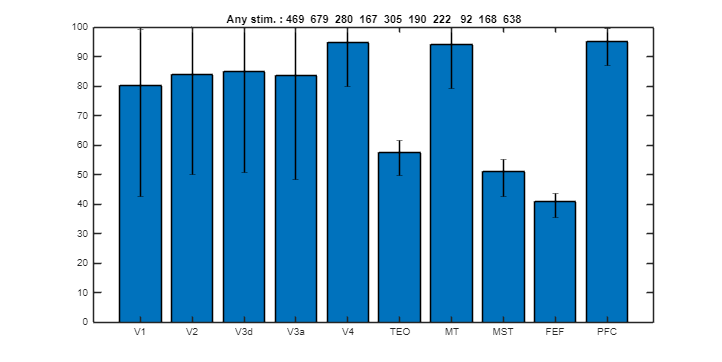

figure("Position", [0 0 2000 1000]);
cl = [0.9 0.1 0.1];
yt = zeros(1, 10);
st = zeros(1, 10);

for k = 1:10

    ths = median(mean(expvard{k}, 2))*0;
    idxp = mean(expvard{k}, 2) > ths;
    t = linspace(-500, 1000, 1500);
    yt(k) = max(abs(max(expvard{k}(idxp, :) - mean(expvard{k}(idxp, :), 'all'))))*100;
    st(k) = 5*max(std(expvard{k}(idxp, :)))*100 / sqrt(min(100, sum(idxp)));
    
end

bar(areaNames, yt);                

hold on

er = errorbar(categorical(areaNames),yt,2*st,st);    
er.Color = [0 0 0];                            
er.LineStyle = 'none';  
ylim([0 100]);

hold off
title("Any stim. : " + num2str(areaCounts));

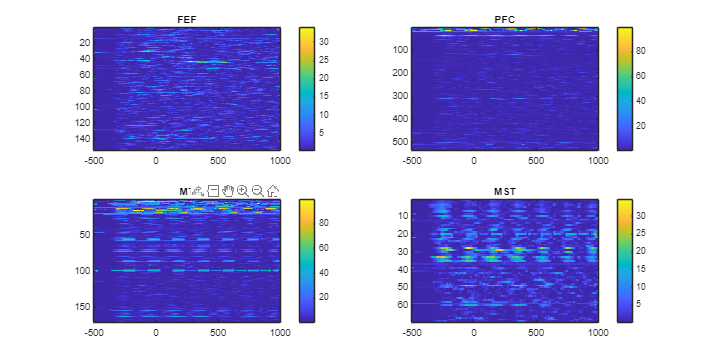

figure("Position", [0 0 2000 1000]);
% cl = [0.9 0.7 0.7];

for k = 6:10

    subplot(2, 2, mod(k-1, 4)+1);
    ths = median(mean(expvard{k}, 2))*.5;
    idxp = mean(expvard{k}, 2) > ths;
    % figure("Position", [0 0 1500 500]);
    t = linspace(-500, 1000, 1500);
    yt = expvard{k}(idxp, :)*100;
    imagesc(yt, "XData", t);colorbar();
    title(areaNames{k});

end


% sgtitle("PEV; neuron by neuron; average by area;");

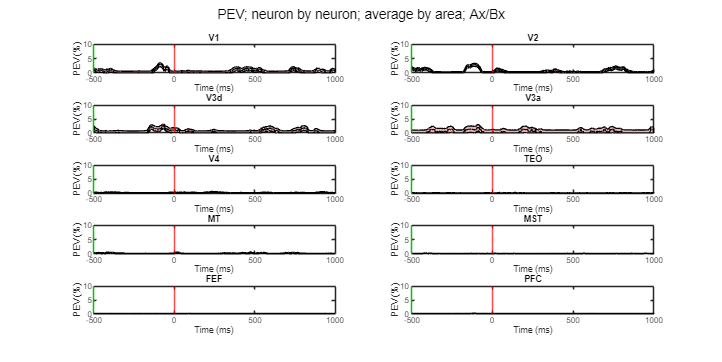

figure("Position", [0 0 2000 1000]);
cl = [0.9 0.7 0.7];

for k = 1:10

    subplot(5, 2, mod(k-1, 10)+1);
    ths = max(mean(expvarz{k}, 2))*0.0;
    if k > 8
        ths = max(mean(expvarz{k}, 2))*0.0;
    end
    idxp = mean(expvarz{k}, 2) > ths;
    % figure("Position", [0 0 1500 500]);
    t = linspace(-500, 1000, 1500);
    yt = detrend(squeeze(mean(expvarz{k}(idxp, :), 1)))'*100;
    yt(yt<0) = 0;
    st = smooth(squeeze(std(expvarz{k}(idxp, :), 1)), 50)*50/sqrt(areaCounts(k));
    stx = smooth(yt + st, 20);stx(stx<0) = 0;
    sty = smooth(yt - st, 20);sty(sty<0) = 0;
    plot(t, stx, "Color", cl);
    hold("on");
    plot(t, sty, "Color", cl);
    patch([t, t(end:-1:1)], [stx;sty(end:-1:1)], cl);
    plot(t, yt, "Color", "k");

    xline(-500, "HandleVisibility", "off", "Color", "g");
    xline(0, "HandleVisibility", "off", "Color", "r");
    xline(1030, "HandleVisibility", "off", "Color", "r");
    xline(2060, "HandleVisibility", "off", "Color", "r");
    xline(3090, "HandleVisibility", "off", "Color", "r");

    title(areaNames{k});
    xlabel("Time (ms)");
    ylabel("PEV (%)");
    xlim([-500 1000]);
    ylim([0 max(max(yt), 10)]);

end

sgtitle("PEV; neuron by neuron; average by area; Ax/Bx");

END